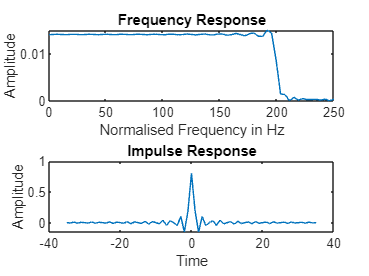

n=input('Enter the order of the filter:');
wc=input('Enter the cutoff frequency:');
ws=input('Enter the sampling frequency:');
type=input('Enter the type of filter:');
wc=wc/ws;
win=input('Enter the type_window:');
if(strcmp(win,'rect'))
b=fir1(n-1,wc,type,rectwin(n));
elseif(strcmp(win,'hamm'))
 b=fir1(n-1,wc,type,hamming(n)); 
else
 b=fir1(n-1,wc,type,hann(n));
end
t=-(n-1)/2:1:(n-1)/2;
l=length(b);
nf=128;
freq=abs(fft(b,nf))/l;
findex=(ws/2)*linspace(0,1,(nf/2)+1);
subplot(2,1,1);
plot(findex,freq(1:(nf/2)+1));
title('Frequency Response');
xlabel('Normalised Frequency in Hz');
ylabel('Amplitude');
subplot(2,1,2);
plot(t,b);
title('Impulse Response');
xlabel('Time');
ylabel('Amplitude');